
%% =========================
% PARÂMETROS
% =========================

N = 8;

d = 5e-3;             % espaçamento entre cristais [m]
x_ref = 0.055;        % referência do centro do array [m]

c = 5825;             % velocidade no bloco [m/s]

useEnvelope = true;   % true = usa envelope Hilbert
doImage = true;       % true = cria imagem TFM 2D

%% =========================
% POSIÇÃO DOS CRISTAIS
% =========================
% Cristais Z = 0
% Array centrado em x_ref

x_elem = ((1:N) - (N+1)/2)*d + x_ref;
z_elem = zeros(1,N);

fprintf('\nPOSIÇÕES DOS CRISTAIS:\n');


POSIÇÕES DOS CRISTAIS:


for k = 1:N
    fprintf('Cristal %d: x = %.4f m | z = %.4f m\n', ...
        k, x_elem(k), z_elem(k));
end

Cristal 1: x = 0.0375 m | z = 0.0000 m
Cristal 2: x = 0.0425 m | z = 0.0000 m
Cristal 3: x = 0.0475 m | z = 0.0000 m
Cristal 4: x = 0.0525 m | z = 0.0000 m
Cristal 5: x = 0.0575 m | z = 0.0000 m
Cristal 6: x = 0.0625 m | z = 0.0000 m
Cristal 7: x = 0.0675 m | z = 0.0000 m
Cristal 8: x = 0.0725 m | z = 0.0000 m



%% =========================
% POSIÇÃO DOS FUROS
% [x profundidade]
%
% Profundidade positiva para dentro do bloco.
%% =========================

holes = [
    0.0538   0.034
    0.0541   0.038
    0.0544   0.042
    % fim da placa (backwall)
    0.0550   0.070
];
Nh = size(holes,1);

fprintf('\nPOSIÇÕES DOS FUROS:\n');


POSIÇÕES DOS FUROS:


for h = 1:Nh
    fprintf('Furo %d: x = %.4f m | z = %.4f m\n', ...
        h, holes(h,1), holes(h,2));
end

Furo 1: x = 0.0538 m | z = 0.0340 m
Furo 2: x = 0.0541 m | z = 0.0380 m
Furo 3: x = 0.0544 m | z = 0.0420 m
Furo 4: x = 0.0550 m | z = 0.0700 m



%% =========================
% NOMES DOS CSV
% =========================

files = {
    'Cristal1.csv'
    'Cristal2.csv'
    'Cristal3.csv'
    'Cristal4.csv'
    'Cristal5.csv'
    'Cristal6.csv'
    'Cristal7.csv'
    'Cristal8.csv'
};

%% =========================
% LER PRIMEIRO CSV
% =========================

M0 = readmatrix(files{1});

t_raw = M0(:,1);

valid0 = ~isnan(t_raw);
t_raw = t_raw(valid0);

[t, ia] = unique(t_raw,'stable');   %porque tinha dados repetidos devido à mudança do intervalo de tempo de leituras

Nt = length(t);

%% =========================
% MATRIZ FMC
% S(tx,rx,time)
% =========================

S = zeros(N,N,Nt);

%% =========================
% LER TODOS OS CSV
% =========================

for tx = 1:N

    M = readmatrix(files{tx});

    M = M(valid0,:);

    if size(M,2) < N+1
        error('O ficheiro %s precisa de 9 colunas: tempo + RX1...RX8.', files{tx});
    end

    for rx = 1:N

        sig_raw = M(:,rx+1);
        sig = sig_raw(ia);

        sig = sig - mean(sig,'omitnan');

        S(tx,rx,:) = reshape(sig,1,1,Nt);

    end
end

%% =========================
% PROCESSAMENTO DOS SINAIS
% =========================

Sproc = zeros(size(S));

for tx = 1:N
    for rx = 1:N

        sig = squeeze(S(tx,rx,:));

        if useEnvelope
            Sproc(tx,rx,:) = abs(hilbert(sig));
        else
            Sproc(tx,rx,:) = sig;
        end

    end
end

%% =========================
% TFM NOS FUROS
% =========================

TFM_holes = zeros(Nh,1);
TFM_pairs = zeros(Nh,N,N);
TOF = zeros(Nh,N,N);

fprintf('\n========================================\n');

fprintf('TEMPOS DE VOO ESPERADOS\n');

TEMPOS DE VOO ESPERADOS


fprintf('========================================\n');


for h = 1:Nh

    xh = holes(h,1);
    zh = holes(h,2);

    soma = 0;

    fprintf('\nFURO %d: x = %.4f m | z = %.4f m\n', h, xh, zh);

    for tx = 1:N

        dtx = sqrt((xh - x_elem(tx))^2 + (zh - z_elem(tx))^2);

        for rx = 1:N

            drx = sqrt((xh - x_elem(rx))^2 + (zh - z_elem(rx))^2);

            tij = (dtx + drx)/c;

            TOF(h,tx,rx) = tij;

            sig = squeeze(Sproc(tx,rx,:));

            valor = interp1(t, sig, tij, 'linear', 0);

            TFM_pairs(h,tx,rx) = valor;

            soma = soma + valor;

            fprintf('TX%d RX%d | dTX = %.3f mm | dRX = %.3f mm | TOF = %.3f us | Valor = %.4g\n', ...
                tx, rx, dtx*1e3, drx*1e3, tij*1e6, valor);

        end
    end

    TFM_holes(h) = soma;

end


FURO 1: x = 0.0538 m | z = 0.0340 m


TX1 RX1 | dTX = 37.705 mm | dRX = 37.705 mm | TOF = 12.946 us | Valor = 0.1699
TX1 RX2 | dTX = 37.705 mm | dRX = 35.829 mm | TOF = 12.624 us | Valor = 0.05056
TX1 RX3 | dTX = 37.705 mm | dRX = 34.579 mm | TOF = 12.409 us | Valor = 0.03995
TX1 RX4 | dTX = 37.705 mm | dRX = 34.025 mm | TOF = 12.314 us | Valor = 0.02977
TX1 RX5 | dTX = 37.705 mm | dRX = 34.201 mm | TOF = 12.344 us | Valor = 0.02585
TX1 RX6 | dTX = 37.705 mm | dRX = 35.095 mm | TOF = 12.498 us | Valor = 0.0223
TX1 RX7 | dTX = 37.705 mm | dRX = 36.656 mm | TOF = 12.766 us | Valor = 0.03829
TX1 RX8 | dTX = 37.705 mm | dRX = 38.803 mm | TOF = 13.135 us | Valor = 0.0188
TX2 RX1 | dTX = 35.829 mm | dRX = 37.705 mm | TOF = 12.624 us | Valor = 0.04244
TX2 RX2 | dTX = 35.829 mm | dRX = 35.829 mm | TOF = 12.302 us | Valor = 0.1563
TX2 RX3 | dTX = 35.829 mm | dRX = 34.579 mm | TOF = 12.087 us | Valor = 0.02807
TX2 RX4 | dTX = 35.829 mm | dRX = 34.025 mm | TOF = 11.992 us | Valor = 0.03608
TX2 RX5 | dTX = 35.829 mm | dRX = 34.201 mm 


FURO 2: x = 0.0541 m | z = 0.0380 m


TX1 RX1 | dTX = 41.468 mm | dRX = 41.468 mm | TOF = 14.238 us | Valor = 0.1666
TX1 RX2 | dTX = 41.468 mm | dRX = 39.731 mm | TOF = 13.940 us | Valor = 0.04072
TX1 RX3 | dTX = 41.468 mm | dRX = 38.569 mm | TOF = 13.740 us | Valor = 0.01688
TX1 RX4 | dTX = 41.468 mm | dRX = 38.034 mm | TOF = 13.648 us | Valor = 0.01887
TX1 RX5 | dTX = 41.468 mm | dRX = 38.152 mm | TOF = 13.669 us | Valor = 0.01241
TX1 RX6 | dTX = 41.468 mm | dRX = 38.917 mm | TOF = 13.800 us | Valor = 0.009842
TX1 RX7 | dTX = 41.468 mm | dRX = 40.293 mm | TOF = 14.036 us | Valor = 0.01712
TX1 RX8 | dTX = 41.468 mm | dRX = 42.220 mm | TOF = 14.367 us | Valor = 0.01884
TX2 RX1 | dTX = 39.731 mm | dRX = 41.468 mm | TOF = 13.940 us | Valor = 0.02014
TX2 RX2 | dTX = 39.731 mm | dRX = 39.731 mm | TOF = 13.642 us | Valor = 0.1535
TX2 RX3 | dTX = 39.731 mm | dRX = 38.569 mm | TOF = 13.442 us | Valor = 0.03162
TX2 RX4 | dTX = 39.731 mm | dRX = 38.034 mm | TOF = 13.350 us | Valor = 0.006279
TX2 RX5 | dTX = 39.731 mm | dRX = 38.152


FURO 3: x = 0.0544 m | z = 0.0420 m


TX1 RX1 | dTX = 45.273 mm | dRX = 45.273 mm | TOF = 15.544 us | Valor = 0.1679
TX1 RX2 | dTX = 45.273 mm | dRX = 43.653 mm | TOF = 15.266 us | Valor = 0.04087
TX1 RX3 | dTX = 45.273 mm | dRX = 42.563 mm | TOF = 15.079 us | Valor = 0.01161
TX1 RX4 | dTX = 45.273 mm | dRX = 42.043 mm | TOF = 14.990 us | Valor = 0.02575
TX1 RX5 | dTX = 45.273 mm | dRX = 42.114 mm | TOF = 15.002 us | Valor = 0.02011
TX1 RX6 | dTX = 45.273 mm | dRX = 42.774 mm | TOF = 15.115 us | Valor = 0.01765
TX1 RX7 | dTX = 45.273 mm | dRX = 43.996 mm | TOF = 15.325 us | Valor = 0.01078
TX1 RX8 | dTX = 45.273 mm | dRX = 45.734 mm | TOF = 15.623 us | Valor = 0.01997
TX2 RX1 | dTX = 43.653 mm | dRX = 45.273 mm | TOF = 15.266 us | Valor = 0.02212
TX2 RX2 | dTX = 43.653 mm | dRX = 43.653 mm | TOF = 14.988 us | Valor = 0.1534
TX2 RX3 | dTX = 43.653 mm | dRX = 42.563 mm | TOF = 14.801 us | Valor = 0.02053
TX2 RX4 | dTX = 43.653 mm | dRX = 42.043 mm | TOF = 14.712 us | Valor = 0.007239
TX2 RX5 | dTX = 43.653 mm | dRX = 42.114 


FURO 4: x = 0.0550 m | z = 0.0700 m


TX1 RX1 | dTX = 72.154 mm | dRX = 72.154 mm | TOF = 24.774 us | Valor = 0.391
TX1 RX2 | dTX = 72.154 mm | dRX = 71.107 mm | TOF = 24.594 us | Valor = 0.06369
TX1 RX3 | dTX = 72.154 mm | dRX = 70.401 mm | TOF = 24.473 us | Valor = 0.01143
TX1 RX4 | dTX = 72.154 mm | dRX = 70.045 mm | TOF = 24.412 us | Valor = 0.04911
TX1 RX5 | dTX = 72.154 mm | dRX = 70.045 mm | TOF = 24.412 us | Valor = 0.03457
TX1 RX6 | dTX = 72.154 mm | dRX = 70.401 mm | TOF = 24.473 us | Valor = 0.04143
TX1 RX7 | dTX = 72.154 mm | dRX = 71.107 mm | TOF = 24.594 us | Valor = 0.03359
TX1 RX8 | dTX = 72.154 mm | dRX = 72.154 mm | TOF = 24.774 us | Valor = 0.03656
TX2 RX1 | dTX = 71.107 mm | dRX = 72.154 mm | TOF = 24.594 us | Valor = 0.02037
TX2 RX2 | dTX = 71.107 mm | dRX = 71.107 mm | TOF = 24.415 us | Valor = 0.344
TX2 RX3 | dTX = 71.107 mm | dRX = 70.401 mm | TOF = 24.293 us | Valor = 0.04029
TX2 RX4 | dTX = 71.107 mm | dRX = 70.045 mm | TOF = 24.232 us | Valor = 0.0292
TX2 RX5 | dTX = 71.107 mm | dRX = 70.045 mm |


%% =========================
% NORMALIZAÇÃO DOS FUROS
% =========================

TFM_norm = TFM_holes ./ max(abs(TFM_holes));
TFM_dB = 20*log10(abs(TFM_norm) + eps);

fprintf('\n========================================\n');

fprintf('RESULTADOS TFM NOS FUROS\n');

RESULTADOS TFM NOS FUROS


fprintf('========================================\n');


for h = 1:Nh
    fprintf('Furo %.1f mm -> Amplitude = %.4g | %.2f dB\n', ...
        holes(h,2)*1e3, TFM_holes(h), TFM_dB(h));
end

Furo 34.0 mm -> Amplitude = 3.311 | -4.59 dB
Furo 38.0 mm -> Amplitude = 2.659 | -6.50 dB
Furo 42.0 mm -> Amplitude = 2.703 | -6.36 dB
Furo 70.0 mm -> Amplitude = 5.618 | 0.00 dB


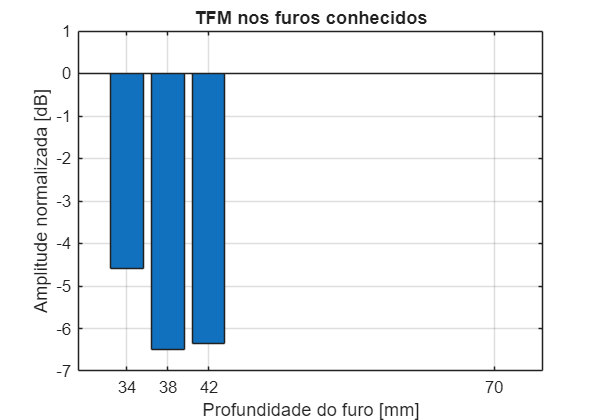


%% =========================
% GRÁFICO - RESULTADO DOS FUROS
% =========================

figure('Position',[100 100 1000 700]);
bar(holes(:,2)*1e3, TFM_dB);
xlabel('Profundidade do furo [mm]');
ylabel('Amplitude normalizada [dB]');
title('TFM nos furos conhecidos');
grid on;

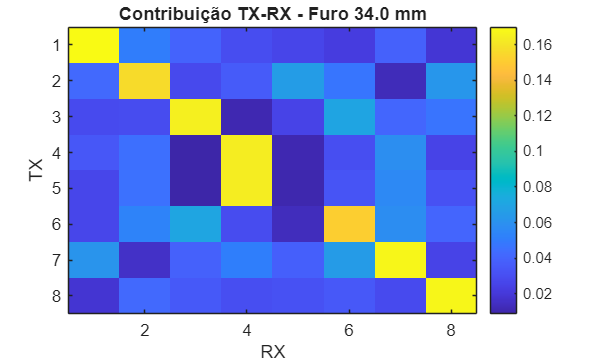

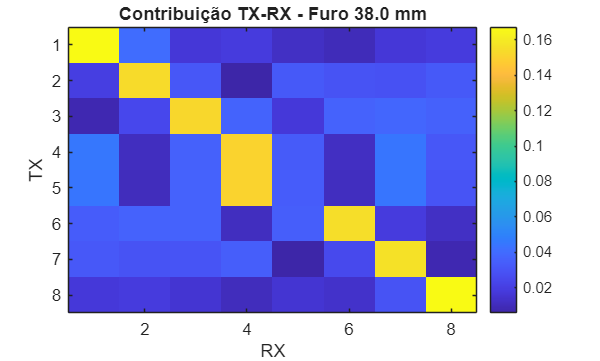

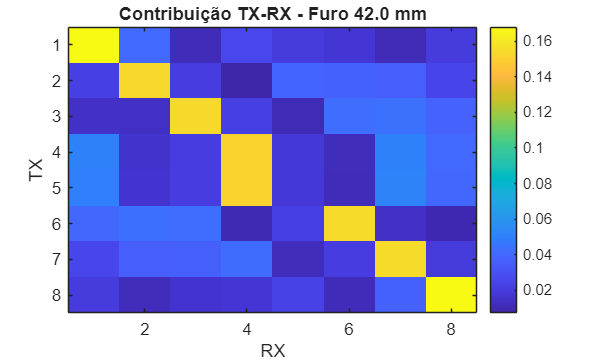

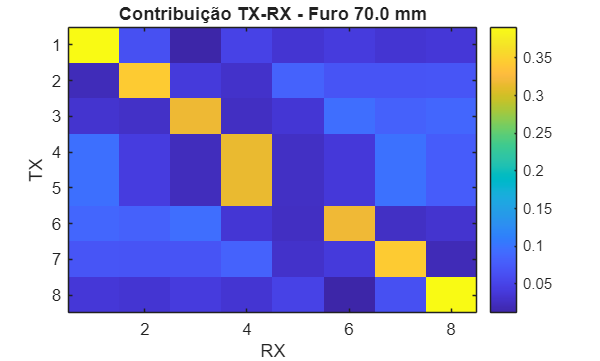


%% =========================
% GRÁFICO - CONTRIBUIÇÃO TX/RX
% =========================

for h = 1:Nh

    figure;
    imagesc(1:N,1:N,squeeze(TFM_pairs(h,:,:)));
    axis normal;
    colorbar;
    xlabel('RX');
    ylabel('TX');
    title(sprintf('Contribuição TX-RX - Furo %.1f mm', holes(h,2)*1e3));

end

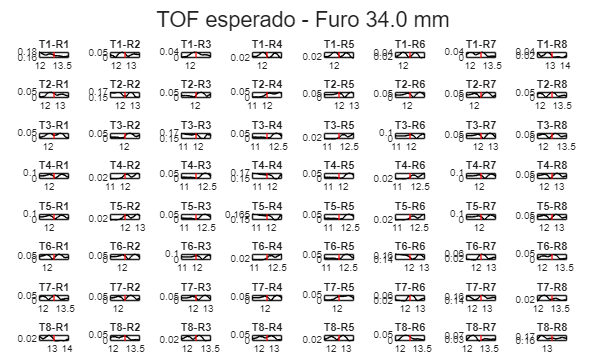

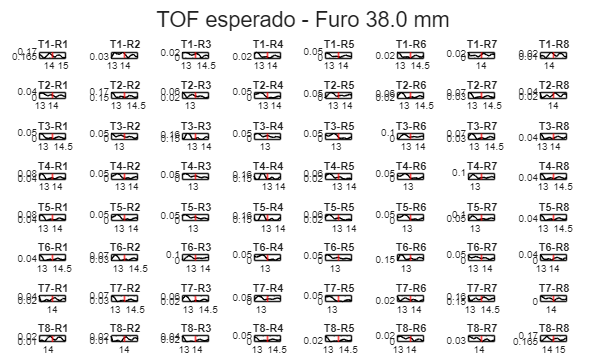

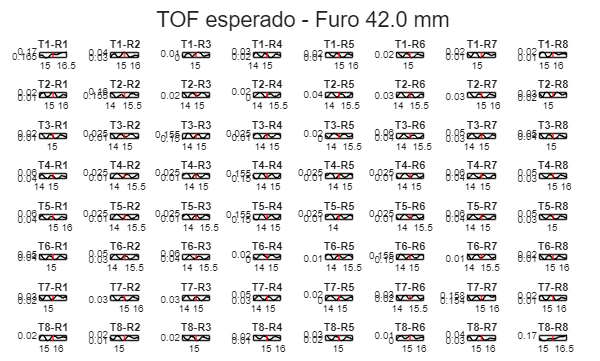

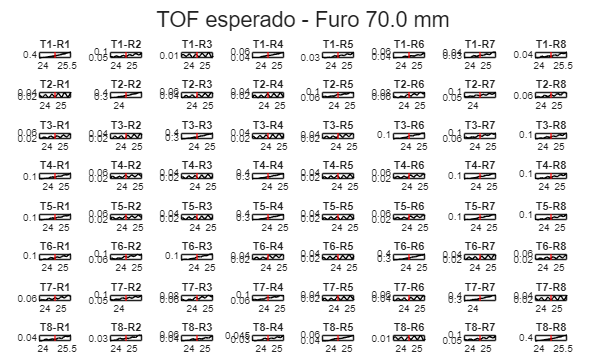


%% =========================
% GRÁFICO - SINAIS COM TOF MARCADO
% =========================

janela = 1.0e-6;   % +/- 1 us à volta do TOF

for h = 1:Nh

    figure;
    tiledlayout(N,N,'TileSpacing','compact','Padding','compact');

    for tx = 1:N
        for rx = 1:N

            nexttile;

            sig = squeeze(Sproc(tx,rx,:));
            plot(t*1e6, sig, 'k');
            hold on;

            tij = TOF(h,tx,rx);
            xline(tij*1e6,'r','LineWidth',1);

            xlim([(tij-janela)*1e6, (tij+janela)*1e6]);

            title(sprintf('T%d-R%d',tx,rx),'FontSize',7);
            set(gca,'FontSize',6);

        end
    end

    sgtitle(sprintf('TOF esperado - Furo %.1f mm', holes(h,2)*1e3));

end

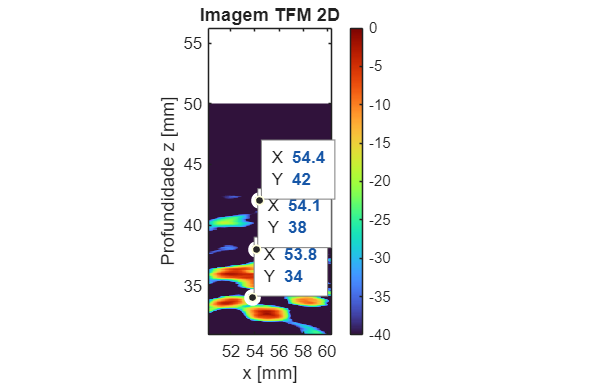


%% =========================
% IMAGEM TFM 2D
% =========================

if doImage

    x_grid = linspace(0.045, 0.065, 301);
    %z_grid = linspace(0.025, 0.05, 351);
    z_grid = linspace(0.025,0.05,501);
    Nx = length(x_grid);
    Nz = length(z_grid);

    IMG = zeros(Nz,Nx);

    for ix = 1:Nx

        x = x_grid(ix);

        for iz = 1:Nz

            z = z_grid(iz);

            soma = 0;

            for tx = 1:N

                dtx = sqrt((x - x_elem(tx))^2 + (z - z_elem(tx))^2);

                for rx = 1:N

                    drx = sqrt((x - x_elem(rx))^2 + (z - z_elem(rx))^2);

                    tij = (dtx + drx)/c;

                    sig = squeeze(Sproc(tx,rx,:));

                    valor = interp1(t, sig, tij, 'linear', 0);

                    soma = soma + valor;

                end
            end

            IMG(iz,ix) = soma;

        end
    end

    %% =========================
% PÓS-PROCESSAMENTO PARA DESTACAR FUROS
% =========================

% amplitude da imagem RF
IMG = abs(IMG);

% remover fundo horizontal
background = median(IMG, 2);

IMG_corr = IMG - background;

% remover negativos
IMG_corr(IMG_corr < 0) = 0;

% reforçar refletores locais
IMG_corr = IMG_corr.^2;

% normalizar
IMG_corr = IMG_corr ./ max(IMG_corr(:));

% converter para dB
IMG_dB = 20*log10(IMG_corr + eps);

% cortar abaixo de -40 dB
IMG_dB(IMG_dB < -40) = -40;

%% =========================
% PLOT
% =========================

figure('Position',[100 100 1100 700]);

imagesc(x_grid*1e3,z_grid*1e3,IMG_dB);

set(gca,'YDir','normal');

pbaspect([1.7 1 1])   % alarga horizontalmente

colormap(jet);
colorbar;

caxis([-40 0]);

xlabel('x [mm]');
ylabel('Profundidade z [mm]');
title('Imagem TFM 2D');

hold on;
plot(holes(:,1)*1e3, holes(:,2)*1e3, ...
    'wo','MarkerSize',8,'LineWidth',2);
    set(gca,'YDir','normal');
    axis image;
    colormap turbo;
    colorbar;
    caxis([-40 0]);

    xlabel('x [mm]');
    ylabel('Profundidade z [mm]');
    title('Imagem TFM 2D');

    hold on;
    plot(holes(:,1)*1e3, holes(:,2)*1e3, 'wo', ...
        'MarkerSize', 8, 'LineWidth', 2);

end